Generated in MATLAB R2023a on by PLX & Luorong  2025-10-26 19:39:12

clear all;
clc;

## Open the GUI window of Image Acquisition toolboxs

% ==============Manual modified parameters====================
root_path = 'E:\1_Data\CC\20260106_CC_live\C135\ROI3';
Hikron = false;
% ============================================================

imageAcquisitionExplorer;
% mkdir(root_path)
device_list = {};
nowtime = string(datetime( 'now'));
nowtime = strrep(nowtime , ':', '-');
% root_path = fullfile(root_path,nowtime);
mkdir(root_path)

## Connect to Camera

Create connection to the device using the specified adaptor with the specified format.

# DONOT operate the imaging window before this section

info = imaqhwinfo('hamamatsu');
num_cameras = length(info.DeviceInfo);
fprintf('%0d camera(s) found.\n',num_cameras)

1 camera(s) found.


for i = 1:num_cameras
    dev_name = info.DeviceInfo(i).DeviceName;
    device_list{end+1} =dev_name;
    fprintf('Device ID %d: %s\n', i, dev_name);
end

Device ID 1: C14440-20UP, S/N: 002325, Bus: USB3



v = cell(num_cameras,1);
src = cell(num_cameras,1);

for i = 1:num_cameras
    v{i} = videoinput("hamamatsu", i, "MONO16_2304x2304_Fast");
    src{i} = getselectedsource(v{i});
end

% if num_cameras == 1
%     v1 = videoinput("hamamatsu", 1, "MONO16_2304x2304_Fast");
% elseif  num_cameras == 2
%     v1 = videoinput("hamamatsu", 1, "MONO16_2304x2304_Fast");
%     v2 = videoinput("hamamatsu", 2, "MONO16_2304x2304_Fast");
% end
fprintf('Camera(s) linked.\n')


## Connect to DAQ

Create connection to the NI controler using the specified adaptor with the specified format.

### Camera 2326 

external trigger: `Dev1/port0/line9`

timing: User2/PFI4                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                   

### Camera 2325 

external trigger: `Dev1/port0/line10`

timing: PFI0

% set trigger mode
trigger = true;
camera_ports = {'port0/line9','port0/line10'};
camera_names = {'C14440-20UP, S/N: 002326, Bus: AS-FBD-2XCXP6-2PE8';'C14440-20UP, S/N: 002325, Bus: USB3'};
% Create the object.
d = daq('ni');
outputcount = 0;
device = 'Dev1';
dinfo = daqlist("ni");
disp(dinfo{1,'DeviceInfo'});

ni: National Instruments(TM) PCIe-6353 (Device ID: 'Dev1')
   Analog input supports:
      7 ranges supported
      Rates from 0.1 to 1250000.0 scans/sec
      32 channels ('ai0' - 'ai31')
      'Voltage' measurement type
   
   Analog output supports:
      -5.0 to +5.0 Volts,-10 to +10 Volts ranges
      Rates from 0.1 to 2857142.9 scans/sec
      4 channels ('ao0','ao1','ao2','ao3')
      'Voltage' measurement type
   
   Digital IO supports:
      Rates from 0.1 to 10000000.0 scans/sec
      48 channels ('port0/line0' - 'port2/line7')
      'InputOnly','OutputOnly','Bidirectional' measurement types
   
   Counter input supports:
      Rates from 0.1 to 100000000.0 scans/sec
      4 channels ('ctr0','ctr1','ctr2','ctr3')
      'EdgeCount','PulseWidth','Frequency','Position' measurement types
   
   Counter output supports:
      Rates from 0.1 to 100000000.0 scans/sec
      4 channels ('ctr0','ctr1','ctr2','ctr3')
      'PulseGeneration' measurement type
   




addinput(d,'Dev1','ai0',"Voltage"); % dummy AI channel is necessary for setting the clock...
% addoutput(d,"Dev1","ctr0","PulseGeneration")

if length(d.Channels) > 1
    outputcount = 0;
    removechannel(d,2:1+num_cameras)
end

for i = 1:num_cameras
    indexC = strfind(camera_names, info.DeviceInfo(i).DeviceName); % 返回 {[1], [], []}
    index = find(~cellfun('isempty', indexC)); % 返回 [1]
    addoutput(d,'Dev1',camera_ports{index},'Digital');
    outputcount = outputcount + 1 ;
    dindex_cameras(i) = outputcount;
end
% dindex_cameras = [1:num_cameras]+1;

% do1 = addoutput(d,'Dev1','port0/line9','Digital');
% dindex_cameras = [1:num_cameras]+1;
%
% if num_cameras == 2
%     do2 = addoutput(d,'Dev1','port0/line10','Digital');
% end

% Set the sample rate to 10,000 Hz.
d.Rate = 1000;
% dindex_cameras = [1:num_cameras]+1;

registed = false;
videostim = false;


## Set light source

# Light intensity must be set in web app

### `Light source`

`Laser405 Dev1/port0/line23`

`Laser445 DO: Dev1/port0/line11 AO:/ao2`

`LEDcyan Dev1/port0/line12`

`LEDgreen Dev1/port0/line16`

`LEDred Dev1/port0/line18`

channel_group = {'Laser405','Laser445','LEDcyan','LEDgreen','LEDred'};
% ==============Manual modified parameters====================
%  manually select used channel, numbers means the index in channel_group.
channel = [3];% ep. [1] means 'Laser405';[2,5] means 'Laser445' and 'LEDred'.
% ==============Manual modified parameters====================

colors = {'m','b','b','g','r'};
light_port = {"port0/line23","port0/line11","port0/line12","port0/line16","port0/line18"};

usedlsrc = channel_group(channel);
imagelsrc = usedlsrc(end-num_cameras+1:end);
stimlsrc = setdiff(usedlsrc,imagelsrc);

num_imlsrc = length(imagelsrc); % num of imaging light source
num_stlsrc = length(stimlsrc); % num of stimulate light source;

if num_stlsrc >1
    warning('Stimulate light number > 1.\n')
end

% dindex_stimlsrc = [1:num_stlsrc] + num_cameras + 1;
% dindex_imlsrc = [1:num_imlsrc] + num_cameras + num_stlsrc + 1;


if length(d.Channels) > num_cameras+1
    outputcount = outputcount - length((num_cameras+2):length(d.Channels));
    removechannel(d,(num_cameras+2):length(d.Channels))
end

dindex_imlsrc=[];
dindex_stimlsrc = [];
aindex_stimlsrc = [];

for i = 1:length(channel)
    addoutput(d,'Dev1',light_port{channel(i)},'Digital');
    outputcount = outputcount + 1 ;
    
    if i <= num_stlsrc
        dindex_stimlsrc(i) = outputcount;
    else
        dindex_imlsrc(i-length(dindex_stimlsrc)) = outputcount;
    end

    if channel(i) == 2
        addoutput(d,'Dev1','ao2','Voltage')
        outputcount = outputcount + 1;
        aindex_stimlsrc = outputcount;
    end
end



fprintf('Light sources set as stimulate light: %s, imaging light: %s',cell2mat(stimlsrc),cell2mat(imagelsrc));

Light sources set as stimulate light: , imaging light: LEDcyan

## Set DMD

### DMD 

`Dev1/port0/line8`

addoutput(d,'Dev1','port0/line8','Digital');
outputcount = outputcount + 1 ;
num_DMD = 1; % num of stimulate light source;
dindex_DMD = [1:num_imlsrc] + num_cameras + num_stlsrc + num_imlsrc + 1;

## Align Two Cameras (if two cameras were used)

Snap photos by two cameras

# Please turn on the light source manually!

% preset cameras
ROI{1} = [0 0 2304 2304];
ROI{2} = [0 0 2304 2304];

% v1.ROIPosition = ROI1;
% src1 = getselectedsource(v1);
% src1.ExposureTime = 20e-03;
% v1.FramesPerTrigger = 10;

v{1}.ROIPosition = ROI{1};
src{1}.ExposureTime = 20e-03;

v{2}.ROIPosition = ROI{2};
src{2}.ExposureTime = 20e-03;

% src2 = getselectedsource(v2);
% v2.FramesPerTrigger = 10;

Snap photos

% x = 0;
% y = 2;
% inputC = [zeros(d.Rate*2-x,num_cameras)];
% inputL = [ones(d.Rate*numSeconds-x,y);zeros(x,y)];
% input = cat(2,inputC,inputL);
% flush(d)
% preload(d,input)
% start(d)
% start(v1)
% if num_cameras == 2
%     start(v2)
% end
im25 = getsnapshot(v{1});
im26 = getsnapshot(v{2});
im25 = im25';

### Register images

fprintf('Registering images...\n')
tic;
registermode ='multimodal' ;
% 创建优化器和度量
[optimizer, metric] = imregconfig(registermode);
% optimizer.GradientMagnitudeTolerance = 1e-2;
% optimizer.MaximumStepLength = 10; % 增大最大步长，应对大偏移
% optimizer.MinimumStepLength = 1e-7; % 减小最小步长，提高最终精度
optimizer.MaximumIterations = 100;  % 增加迭代次数
optimizer.InitialRadius = 0.008;
% optimizer.RelaxationFactor = 0.3;   % 调整松弛因子，影响收敛速度

% % 执行配准
tform = imregtform(im25, im26, 'translation', optimizer, metric);
fprintf(sprintf('Registered after %0d s.\n',toc))
% 提取偏移量
x_offset = tform.T(3,1);
y_offset = tform.T(3,2);

fprintf('计算出的偏移量: x_offset = %.2f, y_offset = %.2f\n', x_offset, y_offset);
fprintf('centered camera2325 = %d, %d\n', round(896 - y_offset), round(896 - x_offset));

registered_im25 = imtranslate(im25, [x_offset,y_offset]);
% 显示配准结果
figure
subplot(1,3,1);
imshowpair(im25,im26);
title('配准前叠加');

% 应用变换
subplot(1,3,2);
imshowpair(registered_im25,im26);
title('配准后叠加');

### Apply offset

registed = true;
ROI{1} = [round(896 - y_offset) round(896 - x_offset) 512 512];
ROI{2} = [896 896 512 512];

v{1}.ROIPosition = ROI{1};
v{2}.ROIPosition = ROI{2};

### Reimaging

im25 = getsnapshot(v{1});
im26 = getsnapshot(v{2});
im25 = im25';

subplot(1,3,3);
imshowpair(im26, im25);
title('更换offset后重新拍摄');


fig_filename = fullfile(root_path, '0_register_image.fig');
png_filename = fullfile(root_path, '0_register_image.png');
mat_filename = fullfile(root_path, '0_register_image.mat');

saveas(gcf, fig_filename, 'fig');
saveas(gcf, png_filename, 'png');
save(mat_filename, 'registermode','optimizer','metric','x_offset','y_offset','tform');

## Configure Default Device Properties for Voltage Recording

Configure videoinput properties to prepare for acquisition.

triggermode = 'immediate'; % immediate 'manual'

% ==============Manual modified parameters====================
bin = 2;
ROI{1} = [896 896 512 512]; % default ROI [896 896 512 512], 1/4 large = [1024 1024 256 256]
ROI{2} = [896 896 512 512]; % default ROI
eptime = 2.5e-03; % exposure time
% ============================================================

if bin == 1
    binmode = 'MONO16_2304x2304_Fast';
elseif bin == 2
    binmode = "MONO16_BIN2x2_1152x1152_Fast";
elseif bin == 4
    binmode = "MONO16_BIN4x4_576x576_Fast";
end

for i = 1:num_cameras
    v{i} = videoinput("hamamatsu", i, binmode);
    src{i} = getselectedsource(v{i});
    fprintf('Camera %d was changed to bin %d.\n',i,bin)
end

Camera 1 was changed to bin 2.



if ~registed
    ROI{1} = round(ROI{1}./bin);
    ROI{2} = round(ROI{2}./bin);
else
    % offset
    v{1}.ROIPosition = round(v{1}.ROIPosition./bin);
    v{2}.ROIPosition = round(v{2}.ROIPosition./bin);
end


for i = 1:num_cameras
    v{i}.ROIPosition = ROI{i};
    v{i}.TriggerRepeat = 0;
    v{i}.FramesPerTrigger = Inf;
    src{i} = getselectedsource(v{i});
    src{i}.ExposureTime = eptime;
    triggerconfig(v{i}, triggermode);
    if trigger
        src{i}.TriggerSource = 'external';
        src{i}.TriggerPolarity = "negative";
        src{i}.TriggerMode = 'start';
    end
end

fprintf(sprintf('Camera(s) set to exposure time %.2d',eptime))

Camera(s) set to exposure time 2.50e-03


% v1.ROIPosition = ROI1;
% v1.TriggerRepeat = 0;
% v1.FramesPerTrigger = Inf;
% src1 = getselectedsource(v1);
% src1.ExposureTime = eptime;
% triggerconfig(v1, triggermode);
% % config = triggerinfo(v1)
%
% if num_cameras == 2
%     v2.ROIPosition = ROI2;
%     v2.TriggerRepeat = 0;
%     v2.FramesPerTrigger = Inf;
%     src2 = getselectedsource(v2);
%     src2.ExposureTime = eptime;
%     triggerconfig(v2, triggermode);
% end

% if trigger
%     src1.TriggerSource = 'external';
%     src1.TriggerPolarity = "negative";
%     src1.TriggerMode = 'start';
%
%     % if num_cameras == 2
%     %     src2.TriggerSource = 'external';
%     %     src2.TriggerPolarity = "negative";
%     %     src2.TriggerMode = 'start';
%     % end
%
% endvideo_path = fullfile(root_path,'orientation_selective_gratings.avi');

## Screen stimulation preparation

### generate grafting drift video

% --- 基础参数设置 ---
videoWidth = 1200;
videoHeight = 700;
frameRate = 60; 
ISI = 0.5;          % 刺激间隔 (秒)
gratingDuration = 1.5; % 刺激持续时间 (秒)

% --- 物理视角参数计算 ---
distToScreen = 9;  % 小鼠到屏幕距离 (cm)
screenWidthCm = 11; % 屏幕物理宽度 (cm)
SF_cpd = 0.04;      % 空间频率 (cycles per degree)
TF_hz = 2;          % 时间频率 (Hz)

% 计算像素/度 (Pixels Per Degree)
totalVisualAngle = 2 * atand((screenWidthCm / 2) / distToScreen);
pixelsPerDegree = videoWidth / totalVisualAngle;
spatialFrequencyPixel = SF_cpd / pixelsPerDegree;

% --- 初始化 ---
orientNum = 8;
orientations = 0:360/orientNum:360*(1-1/orientNum);
gridSize = [videoHeight, videoWidth];
[X, Y] = meshgrid(1:videoWidth, 1:videoHeight);
interFrame = ones(gridSize) * 0.5;

% 1. 创建总视频对象
video_path = fullfile(root_path,sprintf('Drifting grating, SF=%.2f, TF=%.2f, %.2fson, %.2fsoff.avi',SF_cpd,TF_hz,gratingDuration,ISI));
fullVideo = VideoWriter(video_path , 'Uncompressed AVI');
fullVideo.FrameRate = frameRate;
open(fullVideo);
mkdir(fullfile(root_path,'single_orient'))
% --- 循环生成各个方向 ---
for theta = orientations
    % 2. 为当前方向创建独立视频对象
    fileName = fullfile(root_path,'single_orient',sprintf('dir_%d.avi', theta));
    singleVideo = VideoWriter(fileName, 'Uncompressed AVI');
    singleVideo.FrameRate = frameRate;
    open(singleVideo);
    
    fprintf('正在生成方向: %d°...\n', theta);
    
    kx = cosd(theta);
    ky = sind(theta);
    
    % 生成刺激帧
    numFramesStim = round(gratingDuration * frameRate);
    for t = 1:numFramesStim
        currentTime = (t-1) / frameRate;
        phase = 2 * pi * TF_hz * currentTime;
        
        % 计算光栅 (归一化到 0-1)
        grating = 0.5 + 0.5 * sin(2 * pi * spatialFrequencyPixel * (X * kx + Y * ky) - phase);
        
        % 同时写入总视频和单个视频
        writeVideo(fullVideo, grating);
        writeVideo(singleVideo, grating);
    end
    
    % 生成 ISI 帧 (灰阶背景)
    numFramesISI = round(ISI * frameRate);
    for g = 1:numFramesISI
        writeVideo(fullVideo, interFrame);
        writeVideo(singleVideo, interFrame);
    end
    
    % 关闭当前的单个视频
    close(singleVideo);
end

% 关闭总视频
close(fullVideo);

save(fullfile(root_path, 'orientation_gratings_parameters.mat'), ...
    'videoWidth', 'videoHeight', 'frameRate', 'ISI', ...
    'orientations', 'SF_cpd', 'TF_hz', ...
    'gratingDuration', 'video_path','distToScreen','screenWidthCm');

disp('Videos generated successfully!');

# Please drop the video window to the side Screen manually.

### preset stim screen

screen = get(0,'MonitorPosition');
% f = figure('Position',screen(2,:), 'WindowState','fullscreen', 'MenuBar', 'none', 'Resize','off');

stimV = VideoReader(video_path);
FrameRate = stimV.FrameRate;
numFrames = stimV.NumFrames;
numSeconds = numFrames/FrameRate;

trails = zeros(1,numFrames);
videostim = true;

vp = vision.DeployableVideoPlayer();
vp(uint8(zeros(stimV.Height,stimV.Width,3)))
% h = imshow(zeros(stimV.Height,stimV.Width,3),'Border','tight');
frame = readFrame(stimV);
vp(frame)

preset stim screen Psychtool

        psychlaster = max(Screen('Screens'));
        black = BlackIndex(psychlaster);
        [win, winRect] = PsychImaging('OpenWindow', psychlaster, black);
        % % winRect =winRect./1.5;
        % video_path = fullfile(pwd, 'Drifting grating, SF=0.04, TF=2.00, 1.50son, 0.50soff.avi');


        % 打印信息验证
        fprintf('视频加载成功！\n分辨率: %d x %d, 帧率: %.2f\n', width, height, fps);

### Link to gentl Camera

port0/line4

ginfo = imaqhwinfo('gentl');
if isempty(info.DeviceInfo)
    fprintf('no gentl camera found\n')
else
    try
        vh = videoinput("gentl", 1, "Mono8");
        addoutput(d,'Dev1','port0/line4','Digital');
        outputcount = outputcount + 1 ;
        dindex_hcamera = outputcount;
    end
end
Hikron = true;

vh.FramesPerTrigger = Inf;
srch = getselectedsource(vh);
srch.ExposureTime = 10;
triggerconfig(vh, triggermode);
mkdir(fullfile(root_path,'hikron'));

## Input allocation

### Setting recording parameters

% ==============Manual modified parameters====================
trecord = 60; % second.
tstim = 2; % second
tstimdelay = 1; %s
stimcycle = 3; % times
aostep = [2,5,25]; % percentage. length must be same as the stim cycles
% ============================================================
aostep = 5.*aostep./100; % V. length must be same as the stim cycles
if ~videostim
    % nframes = 4000; % manually input
    % trecord = nframes*eptime;dinde
    nframes = trecord/eptime;
else
    nframes = numSeconds/eptime;
    trecord = numSeconds;
end

if Hikron
    nhframes = trecord*100;
end

% tcycles = ceil(trecord + trest); % to aviod last light shut frame.
% ttotal = tcycles*cycles;
% dt = 0:1/d.Rate:ttotal-1/d.Rate;
% input = zeros(tcycles*d.Rate,length(d.Channels)-1);


## Camera input

docameras = zeros(trecord*d.Rate,num_cameras);

for i = 1:num_cameras
    docameras(:,i) = generateDigitalSignal('clock', 1/trecord, d.Rate, trecord);
end

## Light Stimulation Output

if num_stlsrc > 0
    dostimlsrc = generateDigitalSignal('pulse', stimcycle/trecord, d.Rate, trecord,'pulseWidth',tstim,'phase',tstimdelay);
else
    dostimlsrc = [];
end

## Light Stimulation AO Output

if ~isempty(aindex_stimlsrc)
    aostimlsrc = repelem(aostep,round(trecord*d.Rate/length(aostep)))';
    if length(aostimlsrc) < length(dostimlsrc)
        aostimlsrc = [aostimlsrc;zeros(length(dostimlsrc)-length(aostimlsrc),1)];
    end

    aostimlsrc = generateDigitalSignal('pulse', stimcycle/trecord, d.Rate, trecord,'pulseWidth',tstim,'phase',tstimdelay).*aostimlsrc;
    dostimlsrc = [dostimlsrc,aostimlsrc];
end

## Light Imaging Output

doimlsrc = zeros(trecord*d.Rate,num_imlsrc);

for i = 1:num_imlsrc
    doimlsrc(:,i) = generateDigitalSignal('pulse', 1/trecord, d.Rate, trecord,'pulseWidth',trecord);
end

## Hikron Camera Output

if Hikron
    dohcamera = generateDigitalSignal('clock', 1/trecord, d.Rate, trecord);
else
    dohcamera = [];
end

## Allocate to DO Output

output = [docameras, dostimlsrc, doimlsrc,dohcamera];
% halftail = 0.1; % s;
% tailon = [zeros(halftail*d.Rate,num_cameras+num_stlsrc) ones(halftail*d.Rate,num_imlsrc)];
% tailoff = zeros(halftail*d.Rate,num_cameras+num_stlsrc+num_imlsrc);
% taillength = 10;
taillength = ceil(trecord/20)/2 + 1; % s
tail = zeros(taillength*d.Rate,length(d.Channels)-1);
tail(1:taillength*d.Rate/2,dindex_imlsrc(1):dindex_imlsrc(end)) = 1;

headlength = 5;%s
head = zeros(headlength*d.Rate,length(d.Channels)-1);
head(:,dindex_imlsrc(1):dindex_imlsrc(end)) = 1;
%
% input = [input;tailon;tailoff];
output = [head;output; tail];

shut = zeros(d.Rate,size(output,2));

dt = 0:1/d.Rate:(length(output)-1)/d.Rate;
f = figure()

f =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


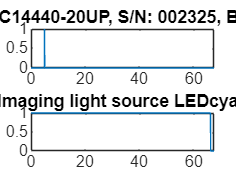


for i = 1:num_cameras
    subplot(length(d.Channels)-1,1,dindex_cameras(i))
    plot(dt,output(:,dindex_cameras(i)))
    title(sprintf('Camera %s',info.DeviceInfo(i).DeviceName));
end

if num_stlsrc > 0
    subplot(length(d.Channels)-1,1,dindex_stimlsrc)
    plot(dt,output(:,dindex_stimlsrc))
    title(sprintf('Stimulate light source DO %s',stimlsrc{1}));
end

if  ~isempty(aindex_stimlsrc)
    subplot(length(d.Channels)-1,1,aindex_stimlsrc)
    plot(dt,output(:,aindex_stimlsrc))
    title(sprintf('Stimulate light source AO %s',stimlsrc{1}));
end

for i = 1:num_imlsrc
    subplot(length(d.Channels)-1,1,dindex_imlsrc(i))
    plot(dt,output(:,dindex_imlsrc(i)))
    title(sprintf('Imaging light source %s',imagelsrc{i}));
end

if Hikron > 0
    subplot(length(d.Channels)-1,1,dindex_hcamera)
    plot(dt,output(:,dindex_hcamera))
    title(sprintf('Hikron camera'));
end

saveas(f, fullfile(root_path, '0_DO_input.fig'), 'fig');
saveas(f, fullfile(root_path, '0_DO_input.png'), 'png');

save(fullfile(root_path, '0_DO_input.mat'),"output")

recordtimes = 0;
% figure()
% for i = 1:size(input,2)
%     if i <= num_cameras
%         input(:,i) = generateDigitalSignal('clock', 1/tcycles, d.Rate, tcycles);
%         subplot(size(input,2),1,i)
%         plot(dt,repmat(input(:,i),cycles,1))
%         title(sprintf('Camera %s',info.DeviceInfo(i).DeviceName));
%     else
%         input(:,i) = generateDigitalSignal('pulse', 1/tcycles, d.Rate, tcycles,'pulseWidth',trecord-1/d.Rate);
%         subplot(size(input,2),1,i)
%         plot(dt,repmat(input(:,i),cycles,1))
%         title(sprintf('Light source %s',channel_group{i+num_cameras+1}));
%     end
%
% end
% inputC = [ones(x,num_cameras);zeros(d.Rate*(numSeconds+1)-x,num_cameras)];
% inputL = [ones(d.Rate*(numSeconds+1)-x,y);zeros(x,y)];
% input = cat(2,inputC,inputL);

## Recording

# Preview in GUI must be OFF before recording

% ==============Manual modified parameters====================
 % this cell is the label of folders which store the recorded tifs. 
recordlabel = {'10%Cyan_60s_bin2'};% for two cameras, use labels like {'Camera1','Camera2'}
cycles = 1; % default 1 repeat recording cycles
trest = 0; % default 0. paused time after recording in each cycle.
savetype = "tif"; % default "tif" = tif_stack file, "mat" = .mat file
% ==============Manual modified parameters====================

recordtimes = recordtimes+1;
nowtime = string(datetime( 'now'));
nowtime = strrep(nowtime , ':', '-');

fprintf('%d cycles will be excuted.\n',cycles);

1 cycles will be excuted.



% mo vie{i} = [];
% movie2 = [];

tstart = tic;
tsave = 0;
broken = 0;
try

for c = 1:cycles
fprintf('Cycles %d is processing.\n',c);

    for i = 1:num_cameras
        save_path{i} = fullfile(root_path,[sprintf('Cam%d_Rec%d_%s_%s',i,recordtimes,recordlabel{i},nowtime) ]);
        mkdir(save_path{i})
        mkdir(fullfile(save_path{i},'DAQ'))
        stop(v{i})
        v{i}.FramesPerTrigger = nframes+1;
        start(v{i})
    end
    if Hikron
        vh.FramesPerTrigger = nhframes+1;
        start(vh)
    end
    fprintf("Camera(s) ready.")

    stop(d)
    flush(d)
    preload(d,output) % worked with start(d) ##1
    fprintf("DAQ ready.")
    

    if videostim

        % % 打开视频
        % [movie, duration, fps, width, height] = Screen('OpenMovie', win, video_path);
        % 
        % % 播放视频 (简易演示)
        % Screen('PlayMovie', movie, 1);
        % 
        % while ~KbCheck
        %     start(d)
        %     tex = Screen('GetMovieImage', win, movie);
        %     if tex <= 0, break; end
        %     Screen('DrawTexture', win, tex);
        %     Screen('Flip', win);
        %     Screen('Close', tex);
        % end


        frame = 1;
        if frame == 1
            stimV = VideoReader(video_path);
            tic;
            start(d) % ##1
            elapse = toc;
        end
        % play video
        while hasFrame(stimV)
            tnow = toc;

            if tnow - elapse >  1/FrameRate
                current_frame = readFrame(stimV);
                vp(current_frame)
                if frame == 1
                    delay = toc;
                end
                trails(frame) = tnow-(frame-1)/FrameRate;
                elapse = tnow;
                frame = frame + 1;
            end
        end
        pause(headlength*1.5+taillength*1.5);
    else
        tic;
        if c > 1
            tlag = toc(tsave);
            fprintf('%d s lagged for next cycle.', tlag);
        else
            tlag = 0;
        end
        elapse = toc;
        start(d) % ##1
        % pause(trecord)
        
        h = waitbar(0,sprintf('Recording process in cycles %d ：0%',c),'Name','Wait','CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
        setappdata(h,'canceling',0)

        % 模拟一个循环计算（例如，100次迭代）
        for i = 1:100

            if getappdata(h,'canceling')
                warndlg('Recording canceled.')
                broken = 1;
                stop(d)
                flush(d)
                preload(d,shut)
                start(d)
                pause(1)
                stop(d)
                flush(d)
                break
                break
            end
            
            % 这里是您的实际计算代码，这里用暂停模拟耗时操作
            pause((trecord+headlength+taillength)/100); % 暂停0.05秒，模拟计算时间

            % 更新进度条：计算当前进度（i/100），并更新消息
            progress = i / 100;
            waitbar(progress, h, sprintf('Process in cycles %d：%.0f%%. Remain time: %d s.',c , progress*100,round(trecord*(1-progress))));
        end

        % 计算完成后关闭进度条
        delete(h);
    end
    toc
    tsave = tic;
       
    stop(d)
    
    if ~broken
        
        for i = 1:num_cameras
            % if i == 1
            current_v = v{i};
            ttest = tic;
            movies{i} = getdata(current_v , current_v.FramesAvailable);
            % movies{i}  = squeeze(movies{i}(:,:,2:end)); % delete first error frame
            movies{i}  = movies{i}(:,:,2:end); % delete first error frame and empty dimension
            % movies{i} = gpuArray(getdata(current_v , current_v.FramesAvailable));
            % movies{i}  = squeeze(movies{i}(:,:,2:end)); % delete first error frame
            toc(ttest)
            cycle_save_path = fullfile(save_path{i},sprintf('Cycle%d', c));
            mkdir(cycle_save_path);
            if savetype == "tif"
                fprintf('Saving movie(s) as tif.\n');
                tmoviesave = tic;
                array2tif(movies{i},fullfile(cycle_save_path,sprintf('%s_rec%d_cycles%d.tif',imagelsrc{i},recordtimes,c)));
                fprintf("Finished saving movie as tif stack after %d s\n", toc(tmoviesave));
        
                saveas(f, fullfile(save_path{i},'DAQ', '0_DO_input.fig'), 'fig');
                saveas(f, fullfile(save_path{i},'DAQ', '0_DO_input.png'), 'png');
                save(fullfile(save_path{i},'DAQ', '0_DO_input.mat'),"output")
            end
            if savetype == "mat"
                matmovie_path = fullfile(cycle_save_path,sprintf('%s_rec%d_cycles%d.mat',imagelsrc{i},recordtimes,c));
                movie = movies{i};
                fprintf("Saving movie as .mat file, please wait...\n")
                tmoviesave = tic;
                % save(matmovie_path, "movie");
                save(matmovie_path, "movie", "-nocompression");
                fprintf("Finished saving movie as .mat file after %d s\n", toc(tmoviesave));
                saveas(f, fullfile(save_path{i},'DAQ', '0_DO_input.fig'), 'fig');
                saveas(f, fullfile(save_path{i},'DAQ', '0_DO_input.png'), 'png');
                save(fullfile(save_path{i},'DAQ', '0_DO_input.mat'),"output")
            end
            stop(v{i})
        end

        if Hikron
            movieh = getdata(vh, vh.FramesAcquired);
            movieh  = squeeze(movieh(:,:,2:end)); % delete first error frame
            fprintf('Saving movie(s) as tif.');
            array2tif(movieh,fullfile(root_path,'hikron',sprintf('Recording_cycles_%d_%s.tif',c,nowtime)));
            stop(vh)
        end

        fprintf('%d s for saved.', toc(tsave));

        if c == cycles
            break
        end

        if trest > toc(tsave)
            fprintf('%d s for waiting.', trest-toc(tsave));
            pause(trest-toc(tsave))
        end
    else
        break
    end

end
toc(tstart)


catch ME

## Run this part when LED or laser cannot be shutdown

Cycles 1 is processing.


Camera(s) ready.

DAQ ready.

Elapsed time is 69.941183 seconds.


Elapsed time is 15.435632 seconds.


Saving movie(s) as tif.


Creating new stack file: E:\1_Data\CC\20260106_CC_live\C135\ROI3\Cam1_Rec11_10%Cyan_60s_bin2_2026-01-06 20-10-12\Cycle1\LEDcyan_rec11_cycles1_stack01.tif
Creating new stack file: E:\1_Data\CC\20260106_CC_live\C135\ROI3\Cam1_Rec11_10%Cyan_60s_bin2_2026-01-06 20-10-12\Cycle1\LEDcyan_rec11_cycles1_stack02.tif
Creating new stack file: E:\1_Data\CC\20260106_CC_live\C135\ROI3\Cam1_Rec11_10%Cyan_60s_bin2_2026-01-06 20-10-12\Cycle1\LEDcyan_rec11_cycles1_stack03.tif
Creating new stack file: E:\1_Data\CC\20260106_CC_live\C135\ROI3\Cam1_Rec11_10%Cyan_60s_bin2_2026-01-06 20-10-12\Cycle1\LEDcyan_rec11_cycles1_stack04.tif
Finished processing after 38 s, Stacked tif created in E:\1_Data\CC\20260106_CC_live\C135\ROI3\Cam1_Rec11_10%Cyan_60s_bin2_2026-01-06 20-10-12\Cycle1\LEDcyan_rec11_cycles1.tif.


Finished saving movie as tif stack after 3.848801e+01 s


5.440221e+01 s for saved.

Elapsed time is 127.733796 seconds.



    error(ME.message)

    stop(d)
    flush(d)
    preload(d,shut)
    start(d)
    pause(1)
    stop(d)
    flush(d)

    errordlg('Recording shutdown. Light source shutdown','Error happend.')

    myCluster = parcluster('Processes');
    delete(myCluster.Jobs);
    gcp;
end

## Online temporary analysis

movie = movies{1}; % for Camera 1
temp_analysis_save_path = fullfile(save_path{1}, 'temp_analysis');
mkdir(temp_analysis_save_path);

### Create map

    %% Create a map (optional)
    t1 = tic; % Start a timer
    fprintf('Creating a map...\n')
    % if the map cannot figure out active cells, please large the bin.
    bin = 1; % defined bin = 4

    [quick_map] = create_map(movie,size(movie,1),size(movie,2),bin);
    map = quick_map;

    % Visualize correlation coefficients as heatmap
    figure()
    imagesc(quick_map);
    colormap turbo;
    title('Sensitivity Map');
    axis image;
    colorbar;
    fig_filename = fullfile(temp_analysis_save_path, '0_Sensitivity_Map.fig');
    png_filename = fullfile(temp_analysis_save_path, '0_Sensitivity_Map.png');
    mat_filename = fullfile(temp_analysis_save_path, '0_Sensitivity_Map.mat');

    saveas(gcf, fig_filename, 'fig');
    saveas(gcf, png_filename, 'png');
    save(mat_filename, 'map');


    t2 = toc(t1); % Get the elapsed time
    fprintf('Finished mask creating after %d s\n',round(t2))

### Cellpose for mask generatopm

    fprintf('cellpose running......\n');
    cp = cellpose(ExecutionEnvironment="gpu");

    movie_vol_2D = squeeze(mean(movie,3));
    avg_image  = (movie_vol_2D - min(movie_vol_2D(:))) / (max(movie_vol_2D(:)) - min(movie_vol_2D(:)));


    avgdia = 15;
    % gamma_image = imadjust(map,[],[],1.2); % recommend raise the gamma factor from 1 to 4.
    gamma_image = imadjust(avg_image,[],[],1.2); % recommend raise the gamma factor from 1 to 4.
    mask = segmentCells2D(cp, gamma_image , ImageCellDiameter = avgdia,CellThreshold = -1, FlowErrorThreshold = 0.4);% CellThreshold = -2, ,  FlowErrorThreshold = 2
    fprintf('%d cells are found.\n',max(mask(:)));
    figure()
    % 使用labeloverlay函数显示图像
    overlayImage = labeloverlay(gamma_image, mask,'Transparency', 0.6);
    % 显示结果
    imshow(overlayImage);
    title('cellpose mask');
    fig_filename = fullfile(temp_analysis_save_path, '0_cellpose_mask.fig');
    png_filename = fullfile(temp_analysis_save_path, '0_cellpose_mask.png');
    mat_filename = fullfile(temp_analysis_save_path, '0_cellpose_mask.mat');

    saveas(gcf, fig_filename, 'fig');
    saveas(gcf, png_filename, 'png');
    save(mat_filename, 'mask');

### ROI selection

    %% Select ROI
    t1 = tic; % Start a timer
    figure()

    % [rois, traces] = select_ROI(movie);
    [rois, traces] = select_ROI(movie, 'mask', []);

自动设置: nrows = 512, ncols = 512


Invalid or deleted object.

Error in select_ROI>wait_for_key (line 211)
key = fig.UserData.space;

Error in select_ROI (line 162)
            key = wait_for_key(fig);

    nrois = max(rois.bwmask,[],'all');

    try
        bwmask = rois.bwmask;
    catch ME

    end
    traces_original = traces;

    % if do not need a map, run the following code:
    % map = [];
    % [bwmask, traces] = select_ROI(movie, nrows, ncols, t, mask, map);

    fig_filename = fullfile(temp_analysis_save_path, '1_raw_trace.fig');
    png_filename = fullfile(temp_analysis_save_path, '1_raw_trace.png');
    roi_filename = fullfile(temp_analysis_save_path, '1_raw_ROI.mat');

    saveas(gcf, fig_filename, 'fig');
    saveas(gcf, png_filename, 'png');
    save(roi_filename, 'rois','avg_image','traces');

    % h = msgbox('All rois saved.', 'Done', 'help');
    % uiwait(h);


    tif_filename = fullfile(temp_analysis_save_path, '1_Averaged.tif');

    tiffile = Tiff(tif_filename, 'w');

    tiffile.setTag('ImageLength', size(movie,2));
    tiffile.setTag('ImageWidth', size(movie,1));
    tiffile.setTag('Photometric', Tiff.Photometric.MinIsBlack);
    tiffile.setTag('BitsPerSample', 16);
    tiffile.setTag('SamplesPerPixel', 1);
    tiffile.setTag('RowsPerStrip', 16);
    tiffile.setTag('PlanarConfiguration', Tiff.PlanarConfiguration.Chunky);
    tiffile.setTag('Compression', Tiff.Compression.None);

    tiffile.setTag('Software', 'MATLAB');
    tiffile.write(uint16(movie_vol_2D));
    tiffile.writeDirectory();
    tiffile.close();
    delete(tiffile)


## CHECK

% save_file = fullfile('Recording.tif');
%
% array2tif(movie1,save_file);
figure
plot(0:eptime:eptime*(size(movies{1},3)-1),normalize(squeeze(mean(mean(movies{1},1),2)),'range'))
hold on;
if num_cameras==2
    plot(0:eptime:eptime*(size(movie2,3)-1),normalize(squeeze(mean(mean(movie2,1),2)),'range'))
end
stimV  = VideoReader(video_path);
stmovie = read(stimV,[1 Inf]);
stmovie = squeeze(stmovie(1,1,:,:));
curvestim = plot(0:1/FrameRate:(size(stmovie,2)-1)/FrameRate,normalize(stmovie(1,:),'range'));
% disp(delay);
% realstim = plot((0:1/FrameRate:(size(stmovie,2)-1)/FrameRate)+delay,normalize(stmovie(1,:),'range'));
% legend("Camera2325",'Camera2326','Yellowlight')
legend('Camera2326','Bluelight')
% title("simutaneously recording by 2 cameras via cube set 1")

figure
plot(trails)